# Show Temporal and Spatial Profiles of Ray-Tracing Channel

Perform ray-tracing between two sites in Chicago. Build a multipath channel model using the ray tracing result, and show the temporal and spatial profiles of the channel. 

Launch Site Viewer with buildings in Chicago. For more information about the osm file, see [1].

viewer = siteviewer("Buildings","chicago.osm");

Create a transmitter site, a receiver site, and a ray tracing propagation model for up to five reflections. By default, ray tracing models use the shooting and bouncing rays (SBR) method. 

tx = txsite("Latitude",41.8800, ...
    "Longitude",-87.6295, ...
    "AntennaAngle",30,"AntennaHeight",10, ...
    "TransmitterFrequency",28e9);
rx = rxsite("Latitude",41.881352, ...
    "Longitude",-87.629771, ...
    "AntennaHeight",30);
pm = propagationModel("raytracing","MaxNumReflections",5);

Show the obstruction to the line-of-sight path.

los(tx,rx)

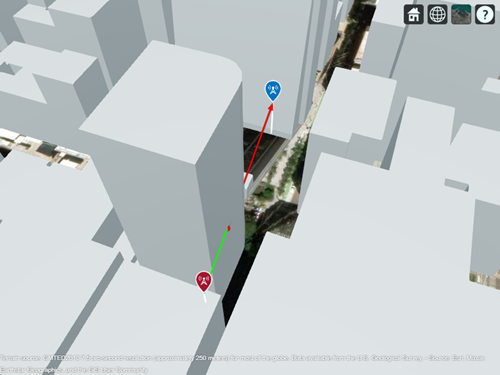

Show the reflected propagation paths using ray tracing.

raytrace(tx,rx,pm)

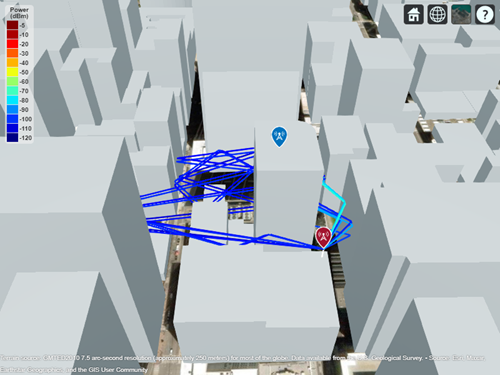

Perform ray tracing to find rays between the transmitter and receiver sites for the specified SBR propagation model. Create a channel model using transmitter site, receiver site, and calculated rays between the sites. Show temporal and spatial profiles of the channel.

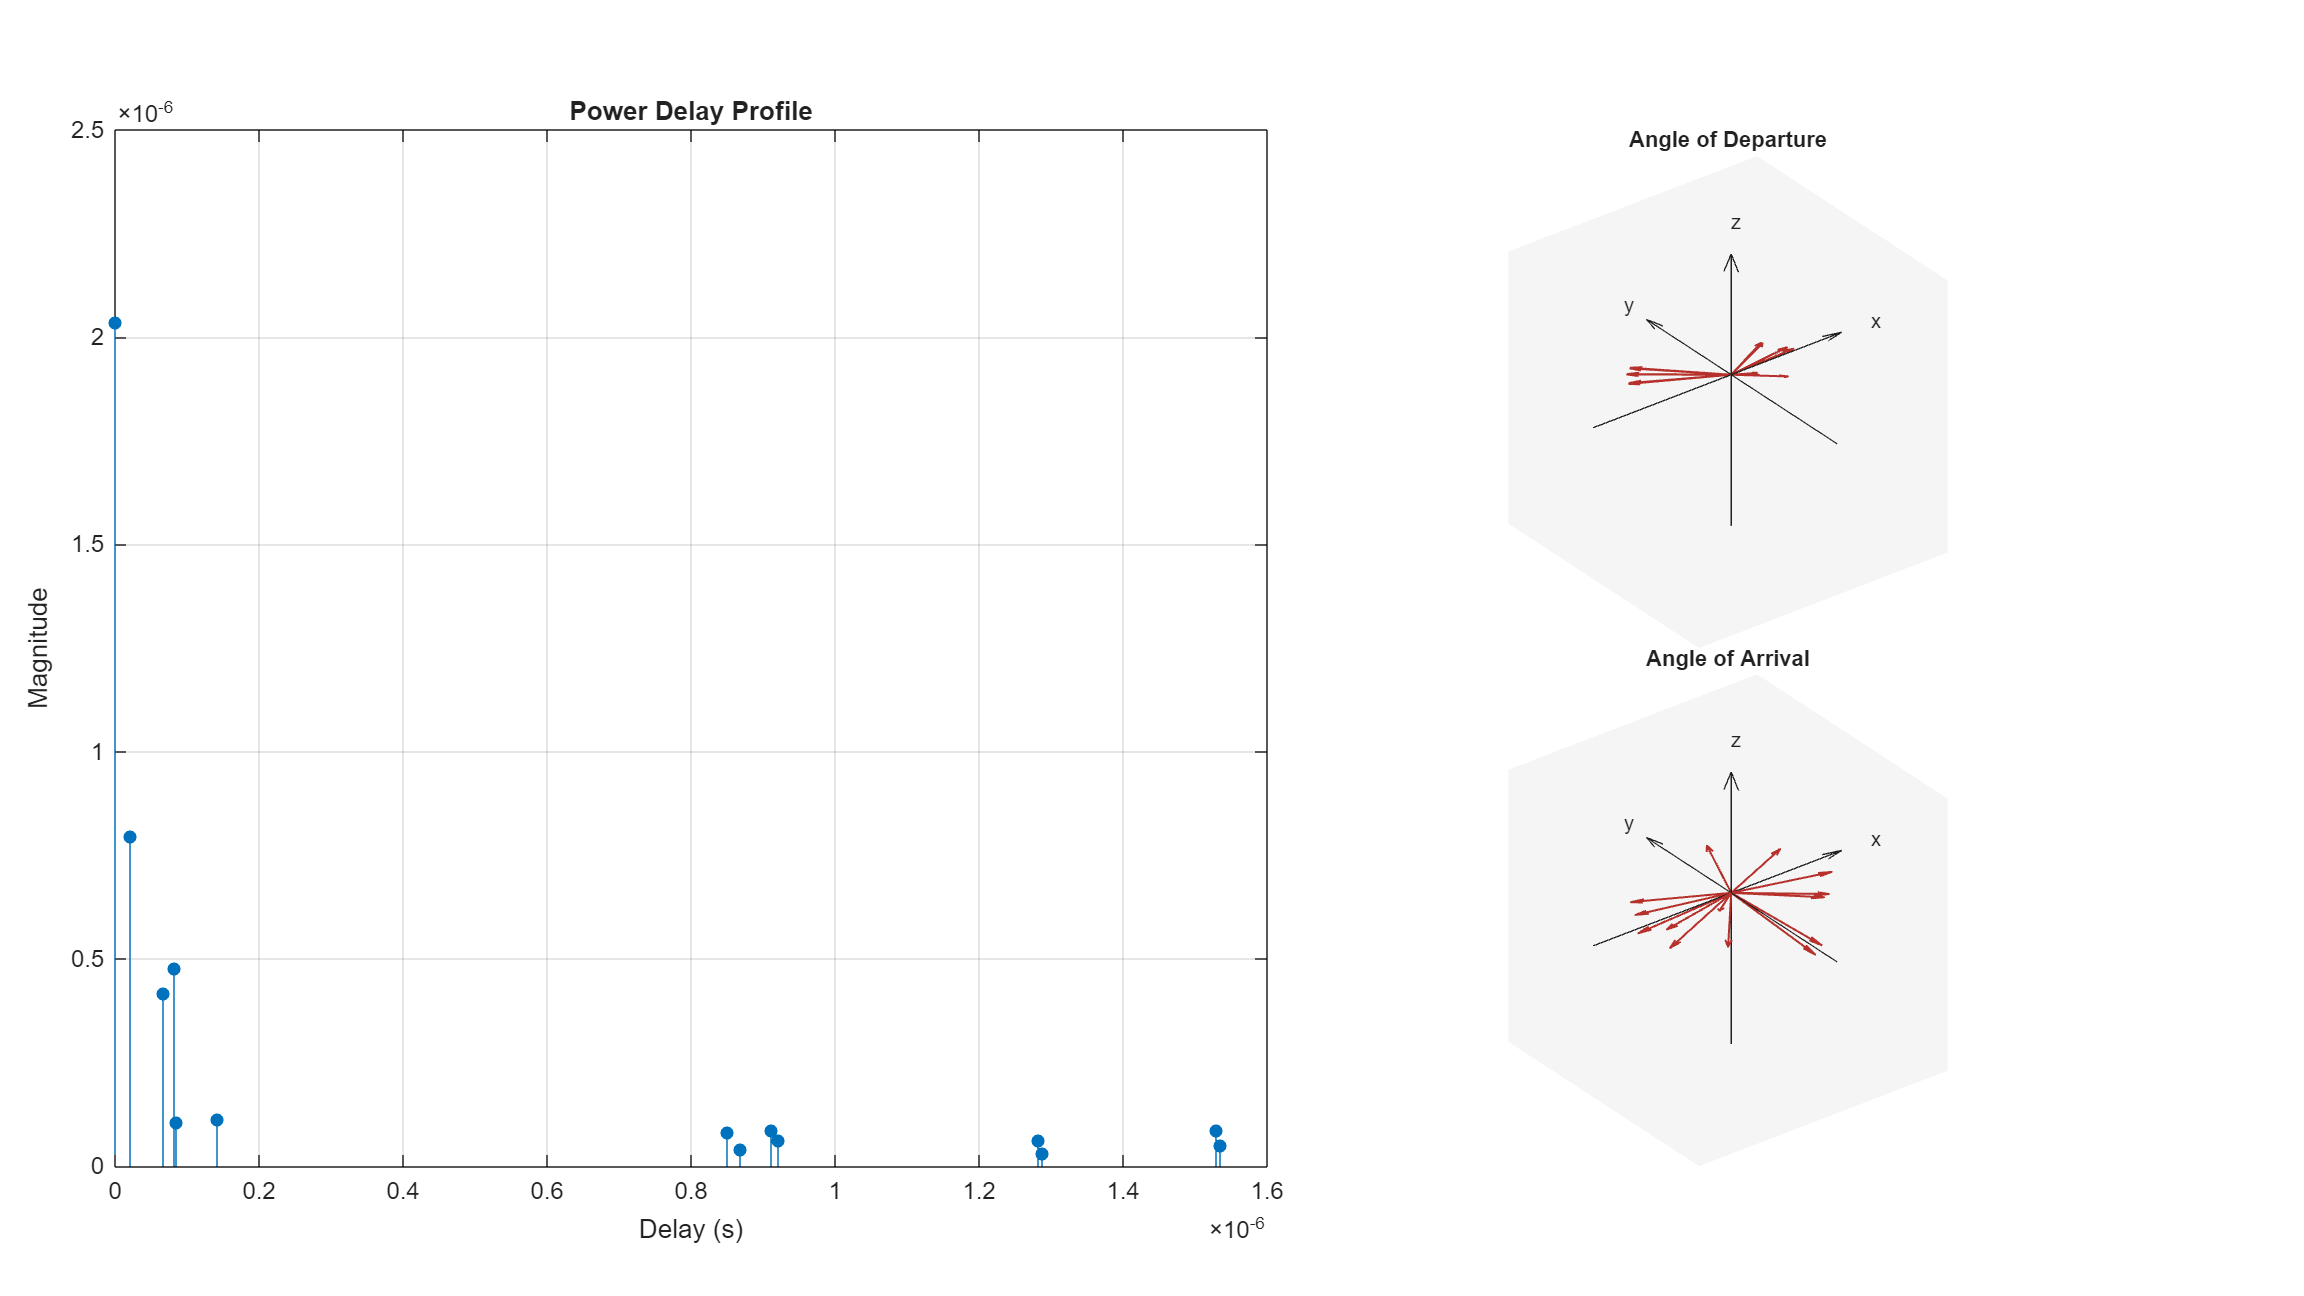

rays = raytrace(tx,rx,pm);
rtchan = comm.RayTracingChannel(rays{1},tx,rx);
showProfile(rtchan);

**Appendix**

[1] The osm file is downloaded from [https://www.openstreetmap.org](https://www.openstreetmap.org/), which provides access to crowd-sourced map data all over the world. The data is licensed under the Open Data Commons Open Database License (ODbL), [https://opendatacommons.org/licenses/odbl/](https://opendatacommons.org/licenses/odbl/).

*Copyright 2020-2022 The MathWorks, Inc.*